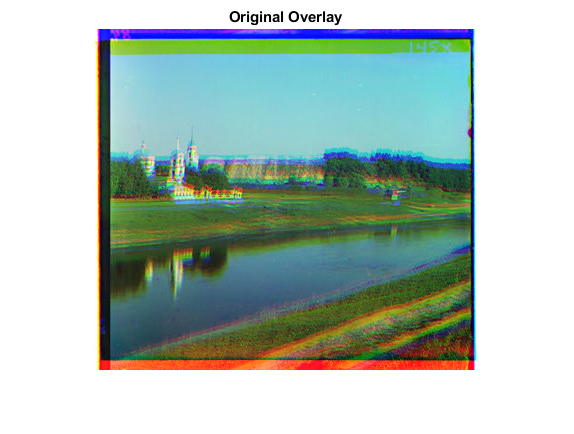

clear all; close all; clc

%Read the image
img = imread('course1image.jpg');
[m,n] = size(img);

% Seperate out the channels by one-thrid of the original images into B,R
% & G respectively.
B = img(1:m/3,:);
G = img(m/3+1:2*m/3,:);
R = img(2*m/3+1:end,:);

% variables to temporarily work with 
ref_img_region = double(G);
ref_img_region = ref_img_region(145:195,145:195);
imgG = double(G);
imgR = double(R);
imgB = double(B);

% Original Overlay
org(:,:,1) =im2double(imgR);
org(:,:,2) = im2double(imgG);
org(:,:,3) = im2double(imgB);
imshow(rescale(org)), title('Original Overlay')


% Declaring the window of search and setting up a blank SSD pile to assess
step = 10;
SSD = zeros(step);


## Assessing for Red.

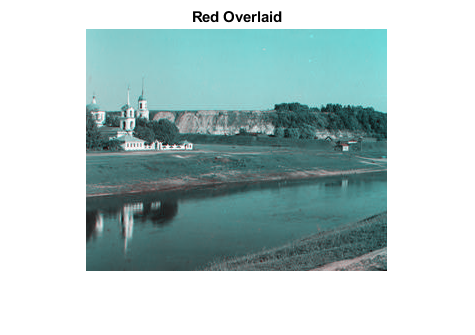


query = imgR;
ref = imgG;

for ii = -step:step
    for jj = -step:step
        shifted = circshift(query, [ii,jj]);
        
        %this takes a sub-region removing noise from shifting loop
%         sub_shifted_query = shifted(20:end-20,20:end-20); 
        sub_shifted_query = shifted(145:195,145:195); 
        sub_ref = ref(145:195,145:195);
        D = sub_shifted_query-sub_ref;
        SD = D.^2;
        SSD(ii+step+1, jj+step+1) = sum(SD(:));        
    end
end

% find location of minimum
[x,y] = find(SSD == min(SSD(:)));

% Transpose query over ref by the following 

transx=x-step-1;
transy=y-step-1;
newR = circshift(imgR,[transx transy]);

% Impose images to confirm

newR = im2uint8(rescale(newR));
newRef = im2uint8(rescale(imgG));
newB = im2uint8(rescale((newR)));


final1(:,:,1) = newR(50:end-50,50:end-50);
final1(:,:,2) = newRef(50:end-50,50:end-50);
final1(:,:,3) = newRef(50:end-50,50:end-50);

figure(); imshow(final1), title('Red Overlaid')

## Assessing for Blue.

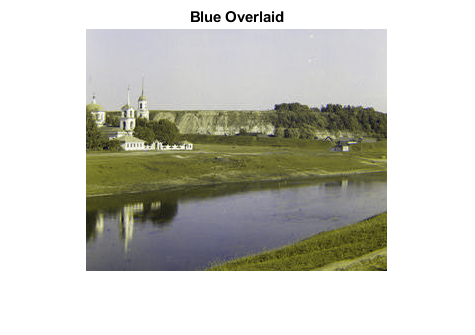


query = imgB;
ref = imgG;

for ii = -step:step
    for jj = -step:step
        shifted = circshift(query, [ii,jj]);
        
        %this takes a sub-region removing noise from shifting loop
        sub_shifted_query = shifted(145:195,145:195); 
        sub_ref = ref(145:195,145:195);
        D = sub_shifted_query-sub_ref;
        SD = D.^2;
        SSD(ii+step+1, jj+step+1) = sum(SD(:));        
    end
end

% find location of minimum
[x,y] = find(SSD == min(SSD(:)));

% Transpose query over ref by the following 

transx=x-step-1;
transy=y-step-1;
newB = circshift(imgB,[transx transy]);

% Impose images to confirm

newRef = im2uint8(rescale(imgG));
newB = im2uint8(rescale(newB));


final2(:,:,1) = newRef(50:end-50,50:end-50);
final2(:,:,2) = newRef(50:end-50,50:end-50);
final2(:,:,3) = newB(50:end-50,50:end-50);
figure(); imshow((final2)), title('Blue Overlaid')

## All Together.

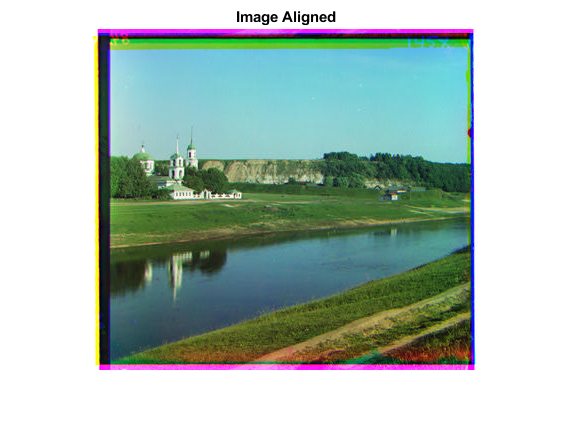


ColorImg_aligned(:,:,1) = newR;
ColorImg_aligned(:,:,2) = newRef;
ColorImg_aligned(:,:,3) = newB;
figure(); imshow(ColorImg_aligned), title('Image Aligned')